Definicja układu dynamiki:

\dot{} 

syms x1 x2 real

f = [x2; -(x1+1)*x1*(x1-1) - x2];

Szukamy punkt urównowagi:

xe = solve(f == [0;0], [x1, x2]);

Sprawdzenie stabilności punktów równowagi - czy można stosować kryterium pośrednie, a jesli tak, to czy jest stabilny:

equilibriums_number = length(xe.x1);

% Sprawdzenie w każdym punkcie równowagi
A_num = cell(equilibriums_number, 1);

stable_index = [];
unstable_index = [];

for index = 1:equilibriums_number
    % Zamiana zmiennych
    syms z1 z2 real
    f_z = subs(f, {x1, x2}, {z1+xe.x1(index), z2+xe.x2(index)});
    % Wyznaczenie jakobianu
    A_z = jacobian(f_z, [z1, z2]);
    % Wyznaczenie r(x)/||x||
    r_ratio_z = simplify((f_z - A_z*[z1;z2]) / norm([z1;z2]));
    % Sprawdzenie granicy - przechodzimy na współrzędne biegunowe
    syms R Theta real
    r_ratio_polar = subs(r_ratio_z, {z1, z2}, {R*cos(Theta), R*sin(Theta)});
    % Granica po promieniu
    L = limit(r_ratio_polar, R, 0);
    if double(norm(L)) ~= 0
        disp("Punkt równowagi " + index + " nie może być zweryfikowany za pomocą kryterium pośredniego.");
        continue;
    end
    % Wyznaczenie numrycznej wartości jakobianu
    A_num{index} = double(subs(A_z, ...
        {z1, z2}, ...
        {0, 0}));
    % Wyznaczenie wartści własnych jakobianu
    e = eig(A_num{index});
    % Sprawdzenie stabilności
    if any(real(e) > 0)
        disp("Punkt równowagi " + index + " jest niestabilny");
        unstable_index = [unstable_index, index];
    else
        if any(real(e) == 0)
            disp("Punkt równowagi " + index + " nie może być określony na podstawie kryterium pośredniego");
        else
            disp("Punkt równowagi " + index + " jest stabilny");
            stable_index = [stable_index, index];
        end
    end
end

Punkt równowagi 1 jest niestabilny


Punkt równowagi 2 jest stabilny
Punkt równowagi 3 jest stabilny


Portret fazowy:

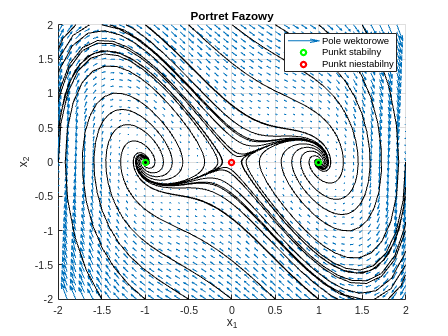

[X1, X2] = meshgrid(-2:0.1:2);
dX1 = X2;
dX2 = -(X1+1).*X1.*(X1-1) - X2;

figure();
grid on;
hold on;
xlabel("x_1");
ylabel("x_2");
title("Portret Fazowy");
xlim([-2, 2]);
ylim([-2, 2]);
legend("show");

quiver(X1, X2, dX1, dX2, 2, "DisplayName", "Pole wektorowe");

X0 = {[-2;2], [-1.5;2], [-1;2], [-0.5;2], [0;2], [0.5;2], [1;2], [1.5;2], [2;2], ...
    [-2;-2], [-1.5;-2], [-1;-2], [-0.5;-2], [0;-2], [0.5;-2], [1;-2], [1.5;-2], [2;-2], ...
    [-2;-2], [-2;-1.5], [-2;-1], [-2;-0.5], [-2;0], [-2;0.5], [-2;1], [-2;1.5], [-2;2], ...
    [2;-2], [2;-1.5], [2;-1], [2;-0.5], [2;0], [2;0.5], [2;1], [2;1.5], [2;2]};

f_num = @(t, x)[x(2);-(x(1)+1)*x(1)*(x(1)-1) - x(2)];

for index = 1:length(X0)
    x0 = X0{index};
    [~, y] = ode45(f_num,0:0.1:100, x0);
    plot(y(:, 1),y(:, 2), "k", "HandleVisibility", "off");
end

% Zaznaczenie punktów równowagi
plot(xe.x1(stable_index), xe.x2(stable_index), "go", "MarkerSize", 5, "LineWidth", 2, "DisplayName", "Punkt stabilny");
plot(xe.x1(unstable_index), xe.x2(unstable_index), "ro", "MarkerSize", 5, "LineWidth", 2, "DisplayName", "Punkt niestabilny");